# Miniprojekt 3 - Tone Control

## Indledning

VIl vil i denne opgave vil vi anvende digital signalbehandling til at justere lyden i en Lyngdorf TDAI-1120 forstærker. Vi vil arbejde audiofiltre og lgoritmer til at opnå en løsning. Forstærkeren indeholder en DSP med forskellige features som tonecontrol, Room Correction og Speaker EQ. Vi vil i denne opgave arbejde med Tone Control. 

## Formål

Vi vil analysere og designe tonekontrol som skal kunne ændre på gain af hhv. bassen og diskanten. Tonekontrol er det førsteled i DSP'en som ses i billedet nedenfor.

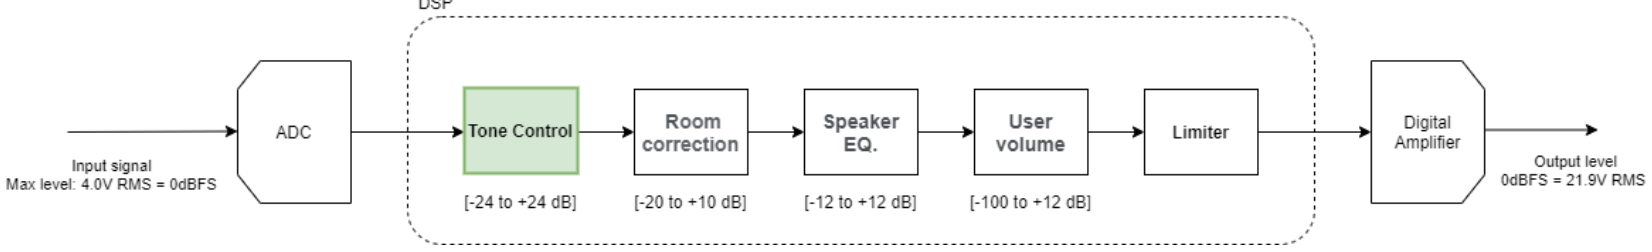

Dette vil vi gøre ved at konstruere to shelving-filtre i kaskade hvor den ene er til bas og den anden til diskant. Kravene er således:

- 2 x IIR filtre (shelving)

- Niveau i hvert bånd +-24dB

## Analyse

Først tages udgangspunkt i diskanten. Ved diskanten skal de høje frekvenser igennem, dvs. et højpas filter skal konstrueres.

### *FilterSelect *funktion

For at producere vores filtre, vil vi lave en eksplicit funktion i matlab. Matlab funktionen vil blive vedhæftet som bilag.

Vi starter med at definere funktionen og kalder den for *FilterSelect. *Den tager fire argumenter hhv. Samplingfrekvens, gain af filtret, cut-off frekcens og om det er et lav pass eller høj pass filter. Funktionen returnere så B og A koefficienterne af IIR filtret.

K og V0 koefficienterne bestemmes som forklaret.

%function [Bout,Aout] = FilterSelect(Fs, gain,Fc, sel)
%K = tan(pi*Fc/Fs);
%V0 = 10^(gain/20);

Nu skal filterkoefficienterne bestemmes. Det ses at nogle af nævnerne for beregningerne er gentagene, hvorfor disse kan pre-defineres.

%denomBoost = (1+sqrt(2)*K+K^2);
%denomCutLF = (V0+sqrt(2*V0)*K+K^2);
%denomCutHF = (1+sqrt(2*V0)*K+V0*K^2);

Først udvælges om det er et filter for bass eller treble, hvilket gøres i den yderste if statement ud fra selector argumentet. Da der er forskellige koefficienter for hvis filteret skal booste eller cutte, laves der en indre indre if statement der tjekker netop dette. Dette gøres ved at se på gain argumentet, da hvis denne er over 0 er der tale om boost ellers cut. Er gain lig med 0, ved vi at filteret er fladt og intet skal ændres ved signalet. Derfor er denne case taget med under boost if statementet.

%if(sel == "bass")
    %boost
%    if(gain >= 0)
%        b0=(1+sqrt(2*V0)*K+V0*K^2)/denomBoost;
%        b1=(2*(V0*K^2-1))/denomBoost;
%        b2=(1-sqrt(2*V0)*K+V0*K^2)/denomBoost;
%        a1=(2*(K^2-1))/denomBoost;
%        a2=((1-sqrt(2)*K+K^2))/denomBoost;
%        %cut
%    elseif (gain < 0)
%        b0=(V0*(1+sqrt(2)*K+K^2))/denomCutLF;
%        b1=(2*V0*(K^2-1))/denomCutLF;
%        b2=(V0*(1-sqrt(2)*K+K^2))/denomCutLF;
%        a1=(2*(K^2-V0))/denomCutLF;
%        a2=(V0-sqrt(2*V0)*K+K^2)/denomCutLF;
%    end
%elseif(sel == "treble")
%    %boost
%    if(gain >= 0)
%        b0=(V0+sqrt(2*V0)*K+K^2)/denomBoost;
%        b1=(2*(K^2-V0))/denomBoost;
%        b2=(V0-sqrt(2*V0)*K+K^2)/denomBoost;
%        a1=(2*(K^2-1))/denomBoost;
%        a2=((1-sqrt(2)*K+K^2))/denomBoost;
%        %cut
%    elseif (gain < 0)
%        b0=(V0*(1+sqrt(2)*K+K^2))/denomCutHF;
%        b1=(2*V0*(K^2-1))/denomCutHF;
%        b2=(V0*(1-sqrt(2)*K+K^2))/denomCutHF;
%        a1=(2*(V0*K^2-1))/denomCutHF;
%        a2=(1-sqrt(2*V0)*K+V0*K^2)/denomCutHF;
%    end
%end

Når hvor koefficienterne er fundet, kan de samles i hver deres array og tildelses til retur værdierne for funktionen.

%Aout = [b0, b1, b2];
%Bout = [1, a1, a2];
%
%end

## Anvendelse af *Tonekontrol*

Nu vil vi anvende funktionen med et konkret eksempel.

%[limbo,Fs]=audioread("dinLydFil.mp3"); %Her kunne man eksempelvis loade sin egen lydfil

Vi loader lydfiler fra miniprojekt 1.

load("miniprojekt1_lydklip.mat");

Der laves nu fire sliders til at justere hhv. cut-off for bass, cut off-off for treble, gain for bass og gain for treble.

Fcb         = 80;      % Cutoff for bass
Fct         = 3500;     % Cutoff for treble

gainBass    =16;       % Gain for bass
gainTreble  =-12;       % Gain for treble

Med de ønskede parametre kan den skabte funktion nu anvendes til at frembringe filterkoefficienterne for de to filtre.

[Bbas,Abas] = FilterSelect(fs_s2,gainBass,Fcb,"bass");         % b og a koeffitienter for bass
[Btreb,Atreb] = FilterSelect(fs_s2,gainTreble,Fct,"treble");   % b og a koeffitienter for treble

Vi bruger nu følgende funktioner til at lave filtrene of derefter kaskade koble de to filtre.

Hbas=dfilt.df2t(Bbas,Abas);     % IIR filter for bass
Htreb=dfilt.df2t(Btreb,Atreb);  % IIR filter for treble
Hcas=dfilt.cascade(Hbas,Htreb); % Kaskade kobling af de to IIR filtre


Der er nu lavet tre knapper der kan anvendes til at afspille det filtrerede signal, det ufiltrerede signal og til at stoppe musikken.

 
filterets2=filter(Hcas,s2);
soundsc(s2,fs_s2)

 
soundsc(s2,fs_s2)

 
clear sound

ddmkds

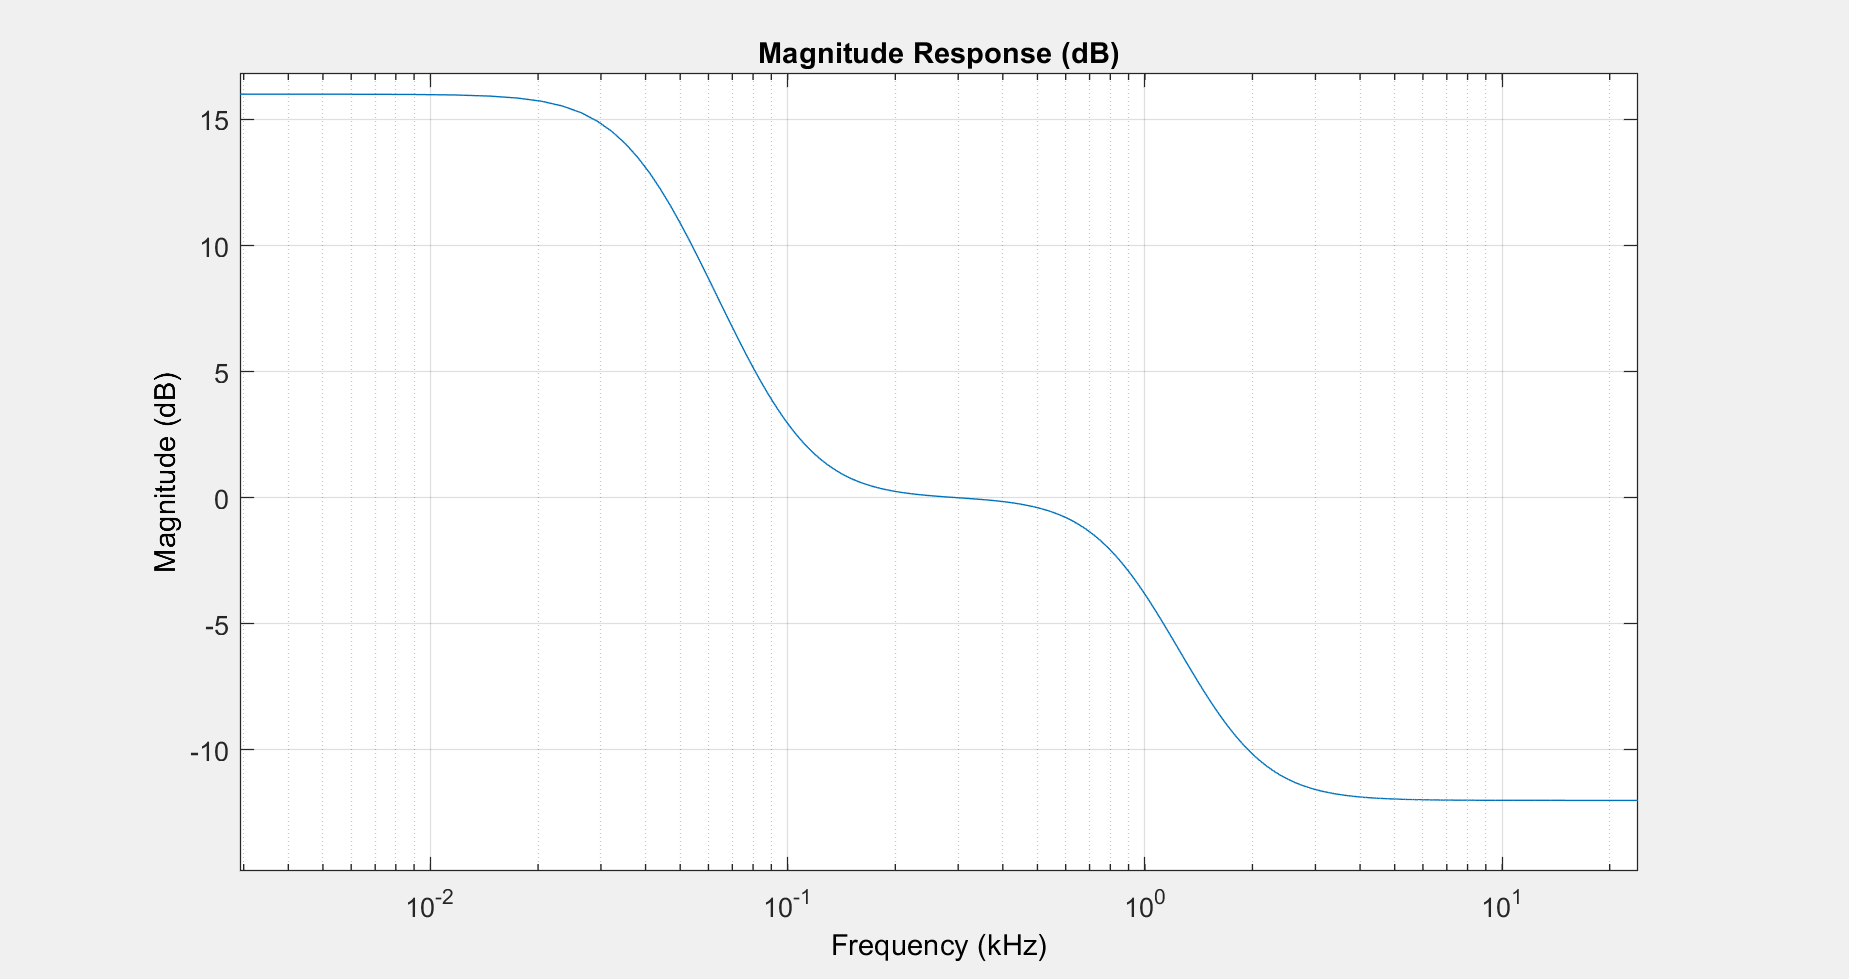

fvtool(Hcas, 'Analysis', 'magnitude', 'Fs', Fs);

dfkopsdsd

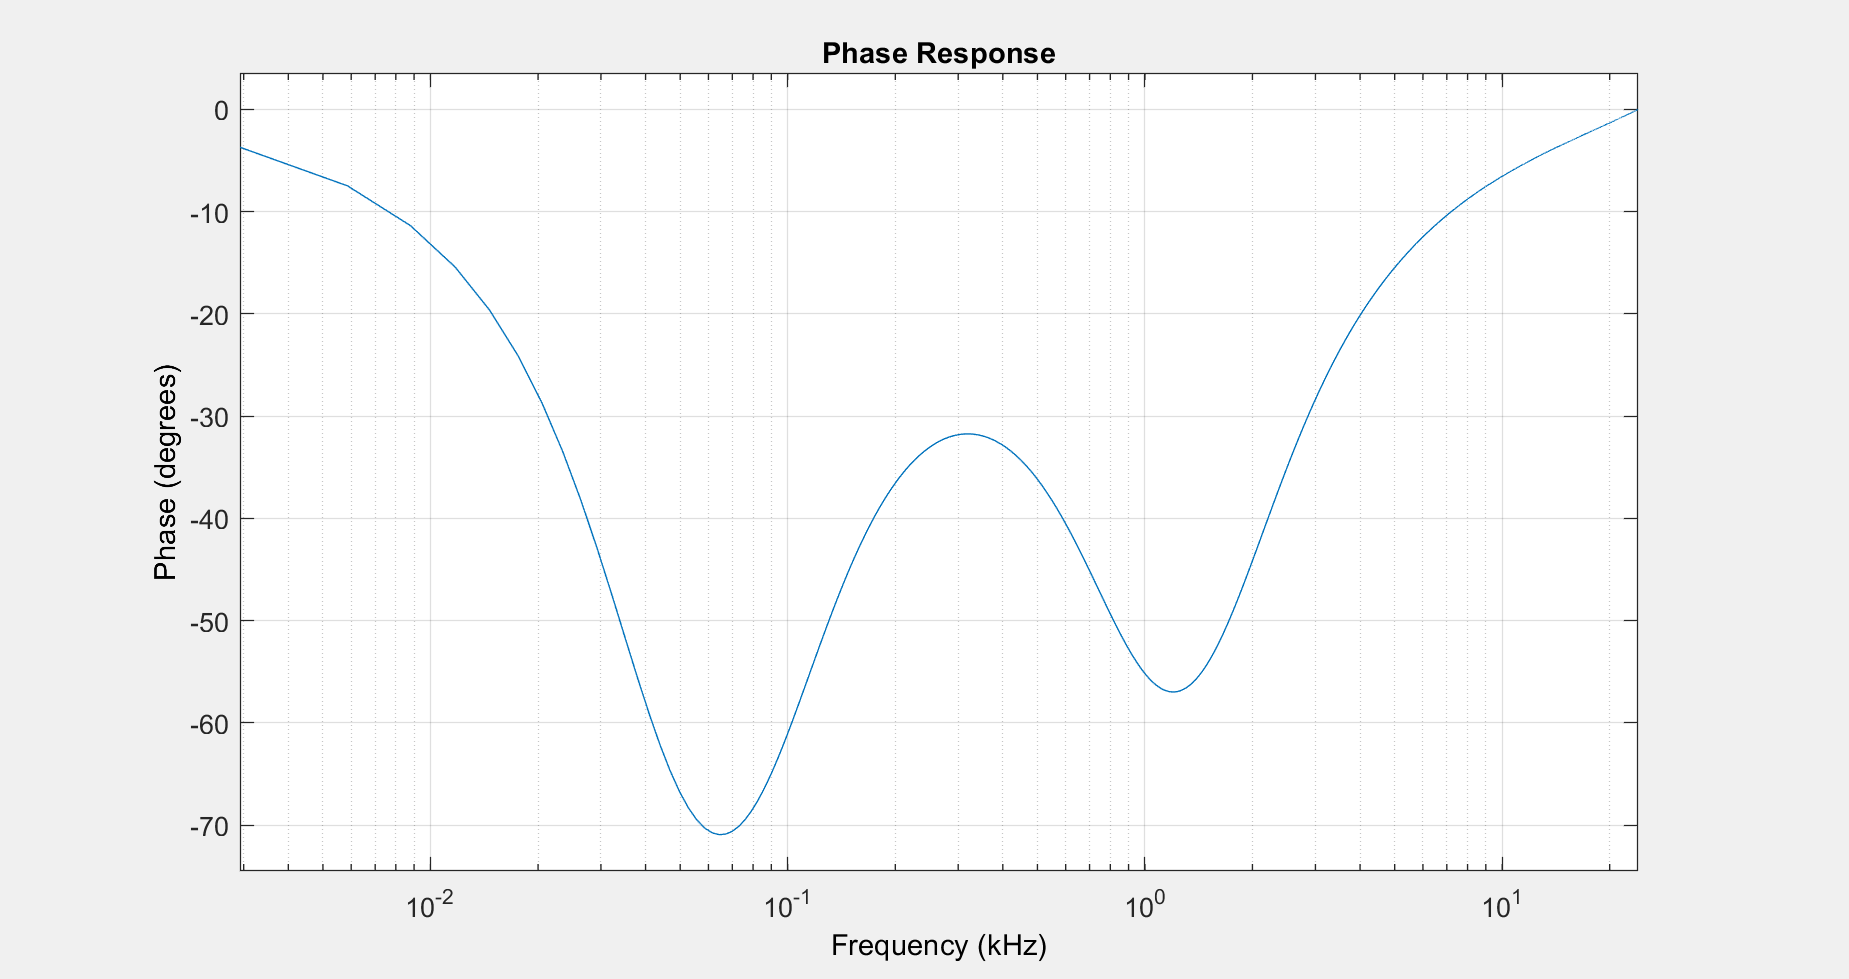

fvtool(Hcas, 'Analysis', 'phase', 'Fs', Fs);

fdsklvksd

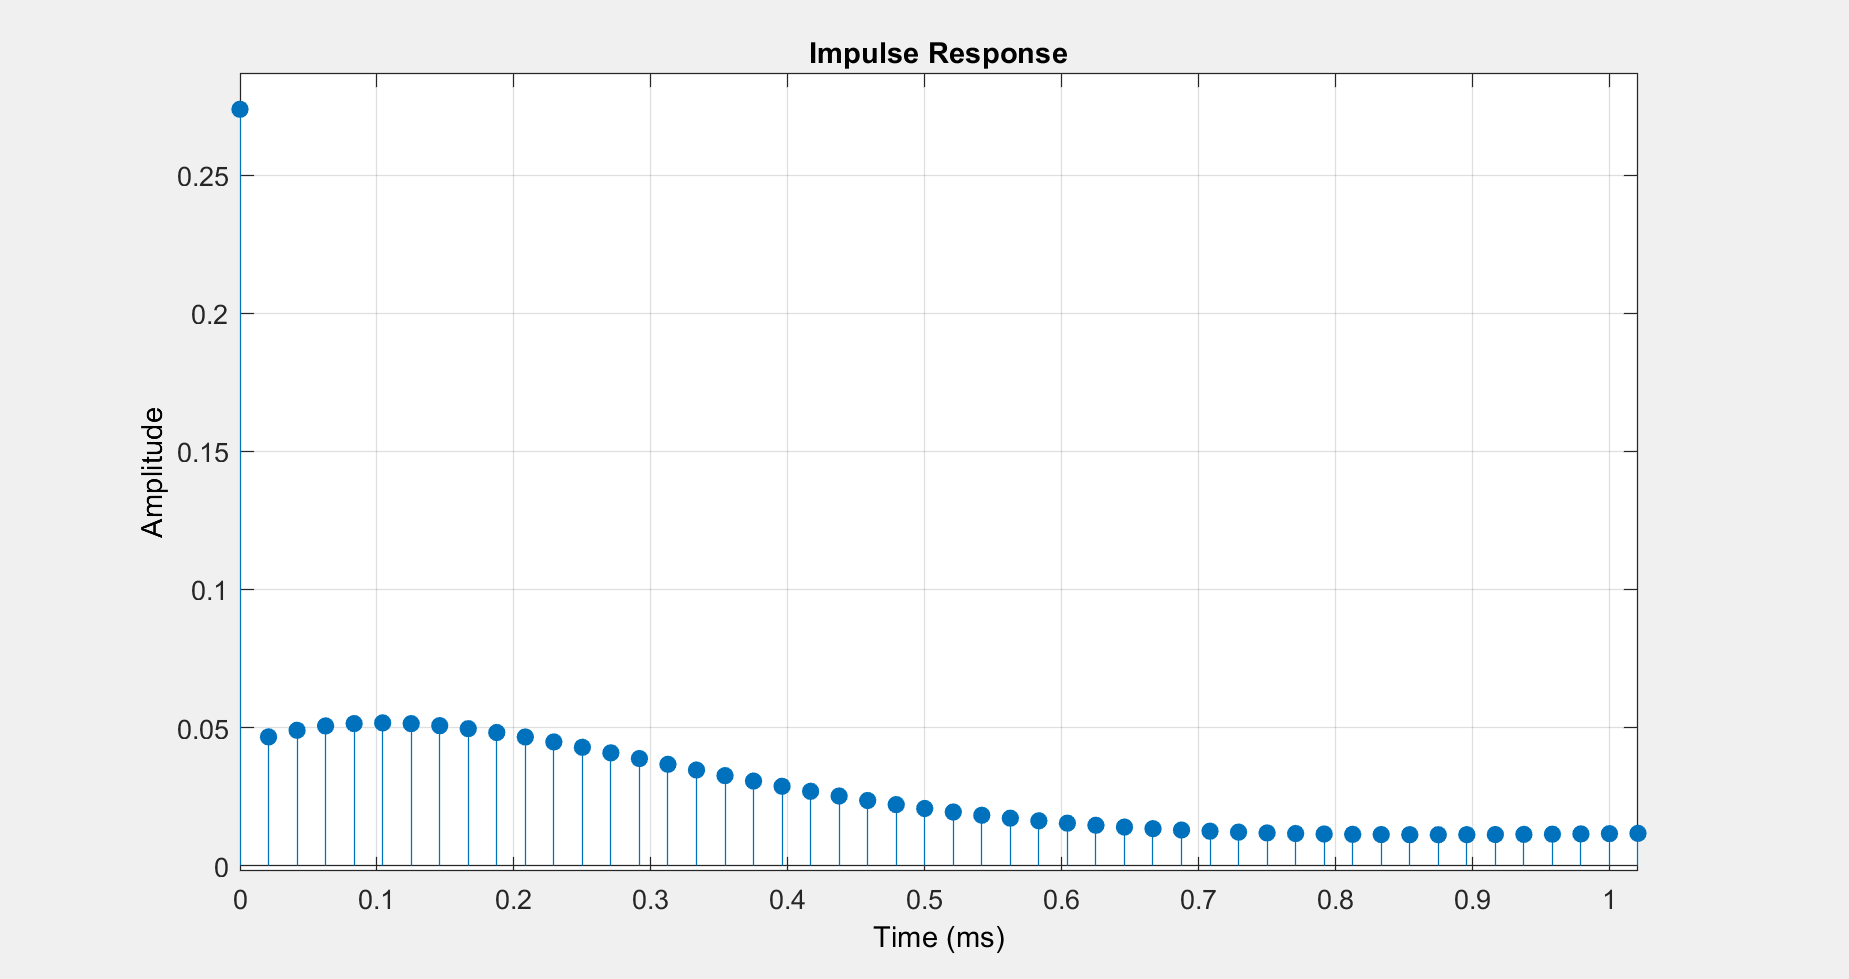

fvtool(Hcas, 'Analysis', 'impulse', 'Fs', Fs);

## Konklusion